# Exploración de distancias

load("occupancy_map_bib.mat")
addpath("dijkstra/")

Mostramos el mapa de ocupación binario con waypoints superpuestos, y sus relaciones de transición. 

show(map)
hold on; 
p = plot(G,'NodeLabel',G.Nodes.Names, 'XData',waypoints(:, 1), 'YData',waypoints(:, 2));
hold off; 

**Prueba de conexidad: **Elegimos 2 puntos de conexión para usar djirstka para encontrar la mejor trayectoria. 

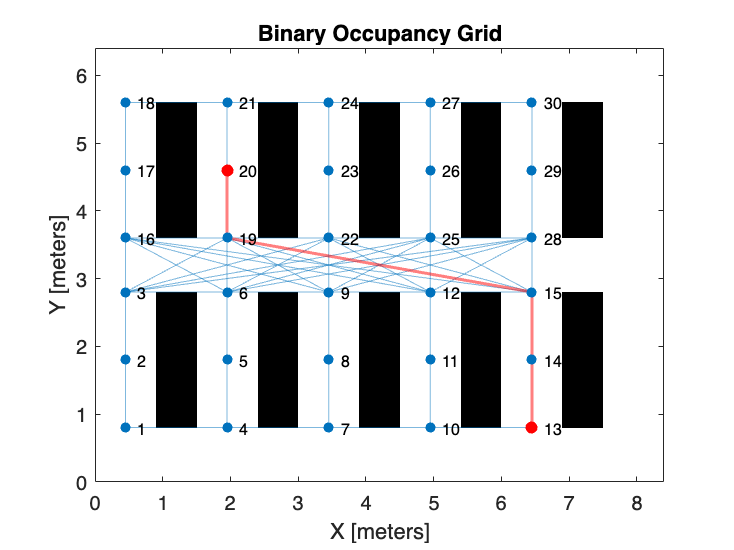

pi = 13; 
pf = 20; 

A = adjacency(G); 
[e, L] = dijkstra(A, pf, pi); 

s = L(1:end - 1); 
t = L(2:end); 

highlight(p,s, t,'EdgeColor','r','LineWidth',1.5); 
highlight(p, [pi, pf], 'NodeColor','red', 'MarkerSize', 5)